# EEG Data Preprocessing

## Loading Dataset

% Initialize Data Parameters

fs = 256; % sample rate in Hz
testNodes = ["Cz","F4"];
H_CzF4 = EEGData(FC(1:6),testNodes,fs);
A_CzF4 = EEGData(FADHD(1:6),testNodes,fs);


H_Test1 = H_CzF4.Task(1);
A_Test1 = A_CzF4.Task(1);

H_subject = subject(1,1);
A_subject = subject(1,0);

H_subject.Data = H_Test1.getSubjectData(H_subject.Id,"Cz");

A_subject.Data = A_Test1.getSubjectData(A_subject.Id,"Cz");


## EDA, Bad Data Removal, and Filtering

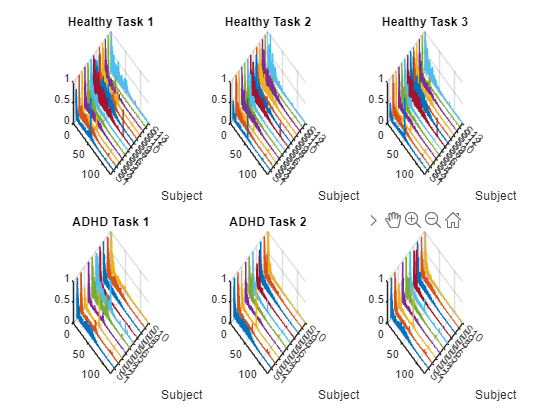

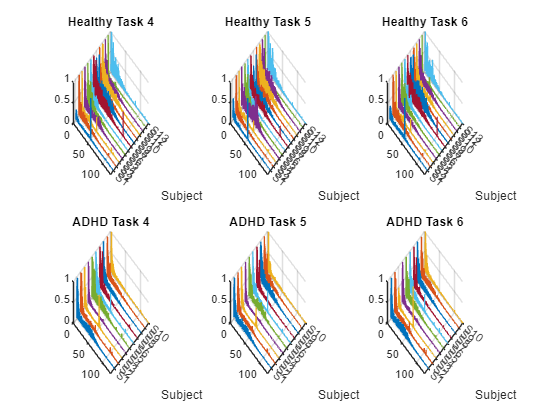

plotFFTComparisonGrid(H_CzF4,A_CzF4);
plotStackedEEGComparisonGrid(H_CzF4,A_CzF4);

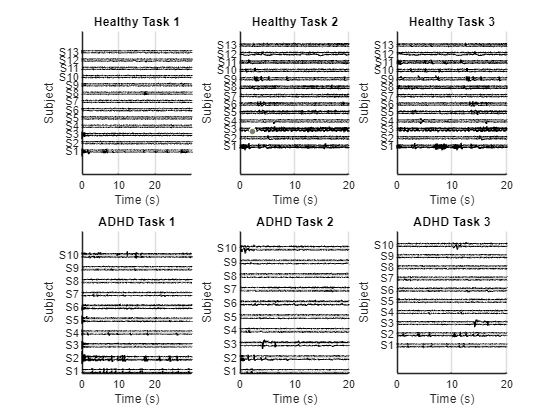

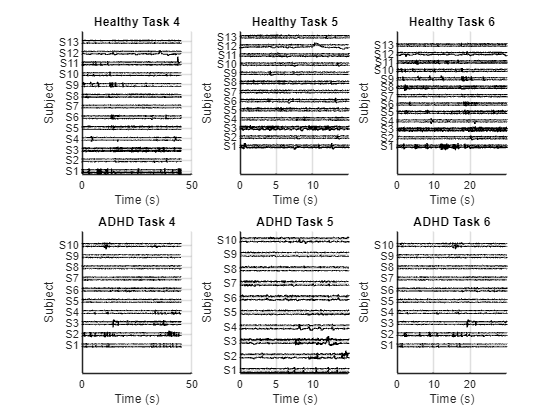

plotPSDComparisonGrid(H_CzF4,A_CzF4);

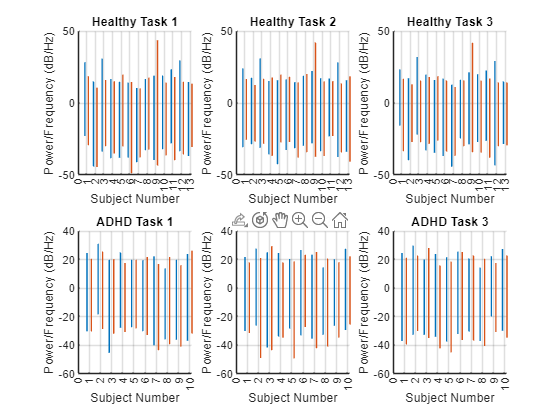

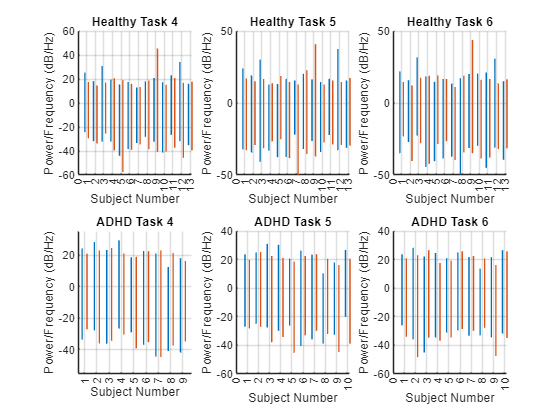

A_CzF4.rmSubject(7);% SUBJECT 7 IN ADHD GROUP STATED TO BE CORRUPTED

ButterHP = designfilt('highpassiir', ...
    'StopbandFrequency',0.5, ...
    'PassbandFrequency',2, ...
    'StopbandAttenuation',20, ...
    'PassbandRipple',1, ...
    'SampleRate',256);

HCF = H_CzF4.rmUnfiltered.filteredData(ButterHP);
ACF = A_CzF4.rmUnfiltered.filteredData(ButterHP);
plotFFTComparisonGrid(HCF,ACF);
plotStackedEEGComparisonGrid(HCF,ACF);


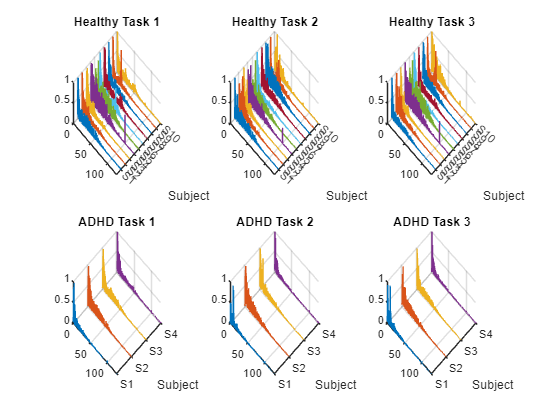

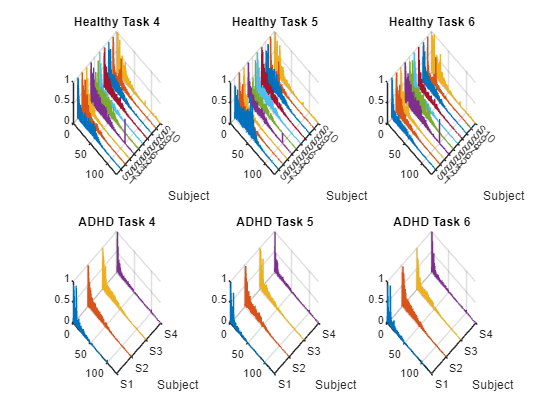

function plotFFTComparisonGrid(H, A)

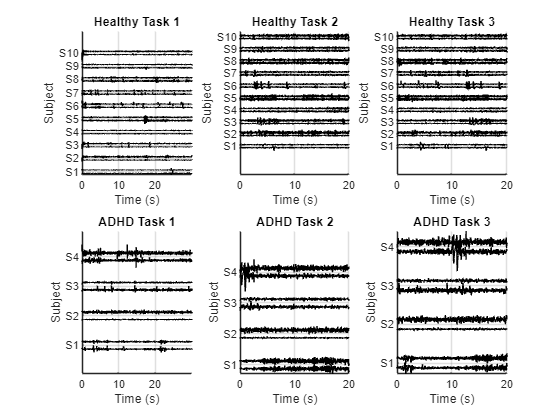

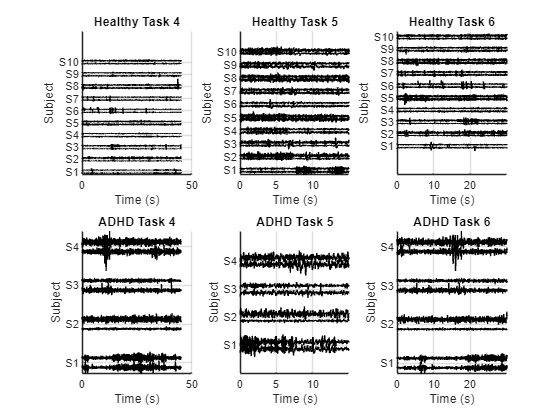

    fftplot = figure;

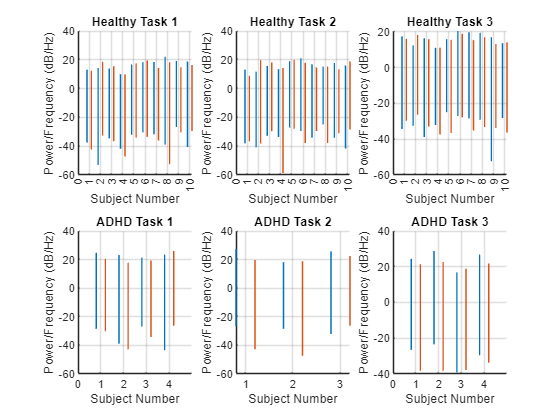

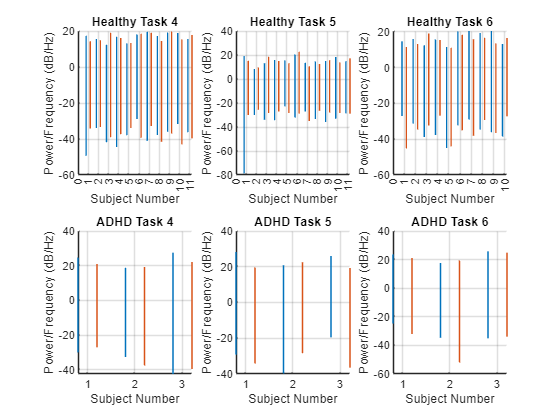

    fftplot2 = figure;


    for i = 1:(H.Ntests / 2)
        figure(fftplot);
        subplot(2, 3, i);
        subjectComparisonPlot(H.Task(i));
        title("Healthy Task " + string(i));

        subplot(2, 3, i+3);
        subjectComparisonPlot(A.Task(i));
        title("ADHD Task " + string(i));

        figure(fftplot2);
        subplot(2, 3, i);
        subjectComparisonPlot(H.Task(i+3));
        title("Healthy Task " + string(i+3));

        subplot(2, 3, i+3);
        subjectComparisonPlot(A.Task(i+3));
        title("ADHD Task " + string(i+3));
    end
end

function plotStackedEEGComparisonGrid(H, A)
    stack1 = figure;
    stack2 = figure;

    for i = 1:(H.Ntests / 2)
        figure(stack1);
        subplot(2, 3, i);
        plotStackedEEG(H.Task(i));
        title("Healthy Task " + string(i));

        subplot(2, 3, i+3);
        plotStackedEEG(A.Task(i));
        title("ADHD Task " + string(i));

        figure(stack2);
        subplot(2, 3, i);
        plotStackedEEG(H.Task(i+3));
        title("Healthy Task " + string(i+3));

        subplot(2, 3, i+3);
        plotStackedEEG(A.Task(i+3));
        title("ADHD Task " + string(i+3));
    end
end
function plotPSDComparisonGrid(H, A)
    psd1 = figure;
    psd2 = figure;

    for i = 1:(H.Ntests / 2)
        figure(psd1);
        subplot(2, 3, i);
        cmpPSD(H.Task(i));
        title("Healthy Task " + string(i));
        xlim([0, 40]);

        subplot(2, 3, i+3);
        cmpPSD(A.Task(i));
        title("ADHD Task " + string(i));
        xlim([0, 40]);

        figure(psd2);
        subplot(2, 3, i);
        cmpPSD(H.Task(i+3));
        title("Healthy Task " + string(i+3));
        xlim([0, 40]);

        subplot(2, 3, i+3);
        cmpPSD(A.Task(i+3));
        title("ADHD Task " + string(i+3));
        xlim([0, 40]);
    end
end
